# Module 2: MATLAB Data Types

## 1. Overview

Variables in MATLAB have different types, representing different forms of data (e.g. numbers, texts...). The good news is -- you don't have to declare a type and change types of varaibles during programming. In this lecture, we're going to briefly know the different types in MATLAB, and focus on the most improtant type -- numeric arrays.

#### 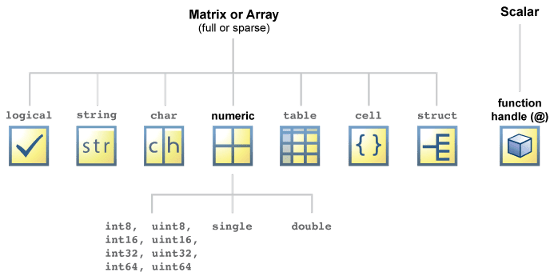

## 2. Inspecting Matlab Data Structures with "Class" Command

class(3) % note that it is not an integer by default

ans = 'double'

class([1,2,3]) % this is the numeric array

ans = 'double'

class('matlab') % note the difference with next line 

ans = 'char'

**char:** Represents text data as a sequence of characters. MATLAB stores strings as arrays of characters enclosed in single quotes (' ').

class("hello world") % You define strings without single quotes

ans = 'string'

class(true)

ans = 'logical'

**logical:** Represents binary values - either true or false. Logical data types are often used in logical operations, conditional statements, and logical indexing.

class(false)

ans = 'logical'

Here "**double**" (short for [double-precision floating-point](https://www.mathworks.com/help/matlab/matlab_prog/floating-point-numbers.html) values) is indeed the default data type for all numeric variables. Note the digits are finite in MATLAB, and therefore are indeed rational.

## **3. Matlab Numeric Arrays**

### 3.1 Different array types and size

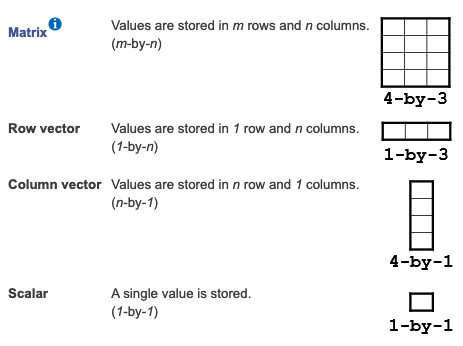

***Example 1: ***[***size***](https://www.mathworks.com/help/matlab/ref/size.html)*** function***

`size(`[`A`](https://www.mathworks.com/help/matlab/ref/size.html#bvfgzsm-1-A)`)` returns a row vector whose elements are the lengths of the corresponding dimensions of `A`. For example, if `A` is a 3-by-4 matrix, then `size(A)` returns the vector `[3 4]`.

[1,2;3,4]

ans =      1     2
     3     4


size([1,2;3,4]) % matrix, use ";" to start a new row

ans =      2     2


[1,2,3,4]

ans =      1     2     3     4


size([1,2,3,4]) % row vector 

ans =      1     4


[1;2;3;4]

ans =      1
     2
     3
     4


size([1;2;3;4]) % column vector

ans =      4     1


size(1) % scalar

ans =      1     1


### ***In-class Exercise 1***

Create the following arrays:

- column vector $\left\lbrack \begin{array}{c}
2\\
5\\
9\\
10\\
3
\end{array}\right\rbrack$;

- row vector $\left\lbrack \begin{array}{cccccc}
3 & 5 & 9 & 3 & 4 & 2
\end{array}\right\rbrack$;

- matrix $\left\lbrack \begin{array}{cc}
1 & 2\\
3 & 4\\
5 & 6
\end{array}\right\rbrack$;

- matrix $\left\lbrack \begin{array}{ccc}
1 & 0 & 0\\
0 & 2 & 0\\
0 & 0 & 3
\end{array}\right\rbrack$. (**Hint:** check out the [diag](https://www.mathworks.com/help/matlab/ref/diag.html?searchHighlight=diag&s_tid=srchtitle_support_results_1_diag) function!)

% write your code here
[2;5;9;8;7]

ans =      2
     5
     9
     8
     7


[3 5 9 3 4 2]

ans =      3     5     9     3     4     2


[1 2; 3 4; 5 6]

ans =      1     2
     3     4
     5     6


diag([1 2 3])

ans =      1     0     0
     0     2     0
     0     0     3


diag([1;2;3])

ans =      1     0     0
     0     2     0
     0     0     3


### 3.2 Different ways to create array (in additional to manually typing)

***Example 2: Evenly-spaced vector*** 

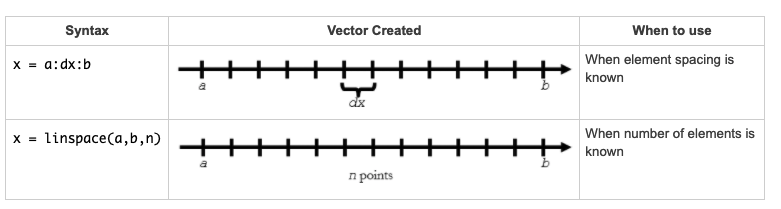

- Method 1: x=a:dx:b

v1 = 1:1e-2:2;
size(v1)

ans =      1   101


length(v1)

ans =    101


v1 % starting from 1 and ending at 2, step size = 0.01

v1 =    1.000000000000000   1.010000000000000   1.020000000000000   1.030000000000000   1.040000000000000   1.050000000000000   1.060000000000000   1.070000000000000   1.080000000000000   1.090000000000000   1.100000000000000   1.110000000000000   1.120000000000000   1.130000000000000   1.140000000000000   1.150000000000000   1.160000000000000   1.170000000000000   1.180000000000000   1.190000000000000   1.200000000000000   1.210000000000000   1.220000000000000   1.230000000000000   1.240000000000000   1.250000000000000   1.260000000000000   1.270000000000000   1.280000000000000   1.290000000000000   1.300000000000000   1.310000000000000   1.320000000000000   1.330000000000000   1.340000000000000   1.350000000000000   1.360000000000000   1.370000000000000   1.380000000000000   1.390000000000000   1.400000000000000   1.410000000000000   1.420000000000000   1.430000000000000   1.440000000000000   1.450000000000000   1.460000000000000   1.470000000000000   1.480000000000000   1.4900000000

1:5 % when step size is 1, it can be omitted

ans =      1     2     3     4     5


- Method 2: using [linspace](https://www.mathworks.com/help/matlab/ref/linspace.html) function

v2 = linspace(1,2,100); % starting from 1 and ending at 2, 100 elements in total
size(v2)

ans =      1   100


v2(1:5) % the first 5 elements

ans =    1.000000000000000   1.010101010101010   1.020202020202020   1.030303030303030   1.040404040404040


v2(end) % the last element

ans =      2


v3 = 2:-1e-2:1 % negative step size

v3 =    2.000000000000000   1.990000000000000   1.980000000000000   1.970000000000000   1.960000000000000   1.950000000000000   1.940000000000000   1.930000000000000   1.920000000000000   1.910000000000000   1.900000000000000   1.890000000000000   1.880000000000000   1.870000000000000   1.860000000000000   1.850000000000000   1.840000000000000   1.830000000000000   1.820000000000000   1.810000000000000   1.800000000000000   1.790000000000000   1.780000000000000   1.770000000000000   1.760000000000000   1.750000000000000   1.740000000000000   1.730000000000000   1.720000000000000   1.710000000000000   1.700000000000000   1.690000000000000   1.680000000000000   1.670000000000000   1.660000000000000   1.650000000000000   1.640000000000000   1.630000000000000   1.620000000000000   1.610000000000000   1.600000000000000   1.590000000000000   1.580000000000000   1.570000000000000   1.560000000000000   1.550000000000000   1.540000000000000   1.530000000000000   1.520000000000000   1.5100000000

size(v3)

ans =      1   101


v4 = linspace(2,1,100)

v4 =    2.000000000000000   1.989898989898990   1.979797979797980   1.969696969696970   1.959595959595960   1.949494949494949   1.939393939393939   1.929292929292929   1.919191919191919   1.909090909090909   1.898989898989899   1.888888888888889   1.878787878787879   1.868686868686869   1.858585858585859   1.848484848484848   1.838383838383838   1.828282828282828   1.818181818181818   1.808080808080808   1.797979797979798   1.787878787878788   1.777777777777778   1.767676767676768   1.757575757575758   1.747474747474747   1.737373737373737   1.727272727272727   1.717171717171717   1.707070707070707   1.696969696969697   1.686868686868687   1.676767676767677   1.666666666666667   1.656565656565657   1.646464646464646   1.636363636363636   1.626262626262626   1.616161616161616   1.606060606060606   1.595959595959596   1.585858585858586   1.575757575757576   1.565656565656566   1.555555555555556   1.545454545454545   1.535353535353535   1.525252525252525   1.515151515151515   1.5050505050

v5 = 1:2:6.1

v5 =      1     3     5


**Question 1:** What are the differences between Method 1 and 2?

Method 1 -- controls the step size. Method 2 -- controls the total number of elements.

**Question 2:** What if we want a evenly-spaced column vector?

linspace(0,5,6)'

ans =      0
     1
     2
     3
     4
     5


### 3.3 Concatenation ("merge")

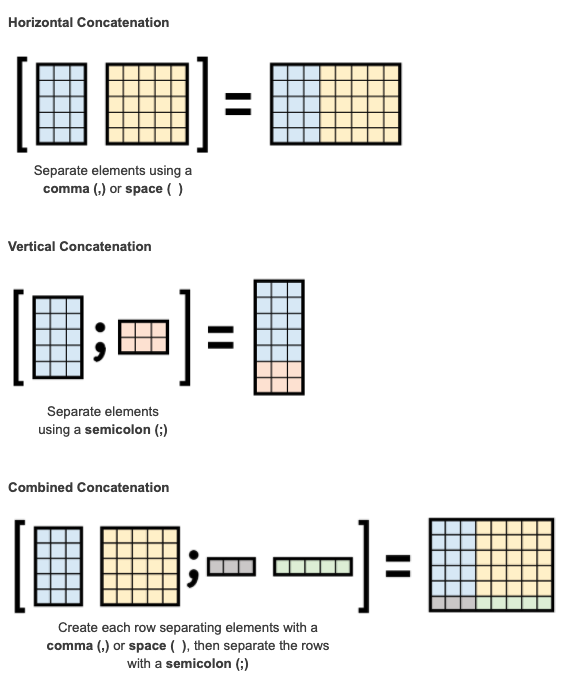

v1 = [1 2]

v1 =      1     2


v2 = [3 4]

v2 =      3     4


v3 = [v1;v2] % vertical

v3 =      1     2
     3     4


v4 = [v1 v2] % horizonal

v4 =      1     2     3     4


[v3;v2] % wrong, size does not match

ans =      1     2
     3     4
     3     4


[v3 v4] % wrong, size does not match

Error using horzcat
Dimensions of arrays being concatenated are not consistent.

### ***In-class Exercise 2***

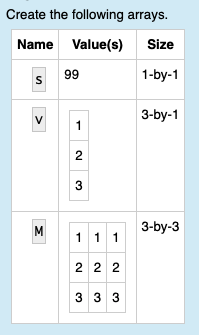

% write your code here
s = [99]

s =     99


v = [1;2;3]

v =      1
     2
     3


M = [1 1 1; 2 2 2; 3 3 3]

M =      1     1     1
     2     2     2
     3     3     3


### ***In-class Exercise 3***

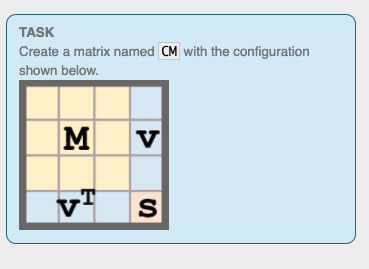

% write your code here
CM = [[M ; v'] [v ; s]]

CM =      1     1     1     1
     2     2     2     2
     3     3     3     3
     1     2     3    99


### ***In-class Exercise 4***

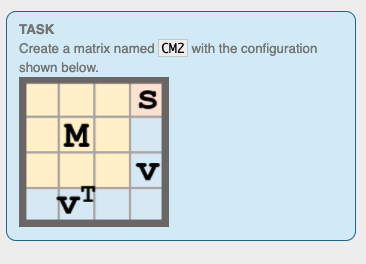

% write your code here
CM2 = [[M ; v'] [s ; v]]

### 3.4 Creating numeric arrays using different functions

zeros(2,3) % all zero 2-by-3

ans =      0     0     0
     0     0     0


ones(3,1) % all one

ans =      1
     1
     1


zeros(5) % square matrix 5-by-5

ans =      0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0


diag([1,2,3]) % create diagonal matrix

ans =      1     0     0
     0     2     0
     0     0     3


rand(6) % all random number with uniform distribution bewteen 0 and 1

ans =    0.458170498977569   0.225902839232842   0.480448223225735   0.916236868496880   0.576933798455541   0.665655851641577
   0.574519340242790   0.753671435668234   0.620899388228014   0.445592860308353   0.248874699524884   0.688429992114826
   0.716698675666096   0.154706539941425   0.231632754140904   0.629267870094414   0.269371865088701   0.306892472672335
   0.804499002252389   0.183948018636843   0.099674786994167   0.290634253188712   0.459572711639389   0.061309599920287
   0.900820233258343   0.773348759312842   0.592454309848796   0.270547428348297   0.430553613841164   0.965775796054983
   0.996501186684391   0.066364515832897   0.831922720843133   0.703572191426076   0.363050629038801   0.777441120263773


randi([10 50],1,5) % generate 5 random integers from the uniform distribution between 10 and 50.

ans =     28    45    14    22    22


### 3.5 Data selection and modification in numeric arrays

***Example 3: Numeric Indexing***

v = 2:2:20;
v

v =      2     4     6     8    10    12    14    16    18    20


% single selection: put the number into ()
v(2) % select the second element

ans =      4


v(end) % select the last element

ans =     20


v(end-1) % select the one before the last element

ans =     18


% multiple selection: put the array into ()
v(1:2:end)

ans =      2     6    10    14    18


**Logic: "1:2:end" when "end=10" --> 1,3,5,7,9 --> select v(1), v(3), v(5), v(7), v(9)**

v([2,4,5])

ans =      4     8    10


***Example 4: Modify the value***

v1 = v; % make a copy of v
v1(1:2:end) = 0; % change v(1), v(3), v(5), v(7), v(9) to 0
v1

v1 =      0     4     0     8     0    12     0    16     0    20


v2 = v;
v2([2,3,4]) = zeros(1,3);
v2

v2 =      2     0     0     0    10    12    14    16    18    20


v3 = v;
v3([2,3,4]) = 0;
v3

v3 =      2     0     0     0    10    12    14    16    18    20


% for the matrix
A = reshape(v,5,2)% change v into 5-by-2 , by default matlab is column pivot

A =      2    12
     4    14
     6    16
     8    18
    10    20


A'

ans =      2     4     6     8    10
    12    14    16    18    20


A*(A')

ans =    148   176   204   232   260
   176   212   248   284   320
   204   248   292   336   380
   232   284   336   388   440
   260   320   380   440   500


A(2,end) % the last element of the second row

ans =     14


A(2:4,2) % the second element of row 2:4

ans =     14
    16
    18


A(4,:) % the 4th row,  note this is different with A(4)

ans =      8    18


A(:,2) % the 2nd column, note this is different with A(2)

ans =     12
    14
    16
    18
    20


A([2,5],1) % submatrix: intersections of row 2, row 5, and column 1

ans =      4
    10


A([2,5],2)

ans =     14
    20


A([2,5],[1,2]) % submatrix

ans =      4    14
    10    20


A(9) % matrix is first "flattened" column-wise, then select as if it is a vector

ans =     18


### 3.6 Logical Indexing

v = 1:4 % generate a vector

v =      1     2     3     4


idx1 = [false, false, true, true] % generate a logical array

idx1 = 1×4 logical array
   0   0   1   1


v(idx1) % select the element when "idx1 = true"

ans =      3     4


idx2 = v>2 % for every element of v, check if it is larger than 2 (true or false)

idx2 = 1×4 logical array
   0   0   1   1


v(idx2) % find the element that are larger than 2

ans =      3     4


v(v>2) % equivalent and faster way

ans =      3     4


R = rand(5)

R =    0.324882214660043   0.884847547274209   0.190723095140142   0.111363977476539   0.998367093708867
   0.377532618402122   0.228309743070042   0.803847381553288   0.713417394568352   0.782454075969894
   0.009980342617278   0.412301182769969   0.398674915219759   0.291888497459228   0.209424537467029
   0.108780938465415   0.888334281543974   0.978183147021599   0.095206679681914   0.736219576379073
   0.764723999782364   0.928906320561663   0.363580533009840   0.664199309886331   0.206804684702861


R(R>.5)

ans =    0.764723999782364
   0.884847547274209
   0.888334281543974
   0.928906320561663
   0.803847381553288
   0.978183147021599
   0.713417394568352
   0.664199309886331
   0.998367093708867
   0.782454075969894


% what if we want to know the location?
idx3 = R>.5 

idx3 = 5×5 logical array
   0   1   0   0   1
   0   0   1   1   1
   0   0   0   0   0
   0   1   1   0   1
   1   1   0   1   0


## 4. Other useful links

**Array Indexing help page in MATLAB: **[https://www.mathworks.com/help/matlab/math/array-indexing.html](https://www.mathworks.com/help/matlab/math/array-indexing.html)

**Christopher Davis**’s videos about MATLAB: [https://www.youtube.com/playlist?list=PLHfGN68wSbbLOFWE0Z_uFLdXjax-evW-h](https://www.youtube.com/playlist?list=PLHfGN68wSbbLOFWE0Z_uFLdXjax-evW-h)

**Yasmeen Baki**’s videos about MATLAB: [https://www.youtube.com/playlist?list=PL6ue_xaI6w4NFUSQqGkzwnW1jJgfP5tNG](https://www.youtube.com/playlist?list=PL6ue_xaI6w4NFUSQqGkzwnW1jJgfP5tNG) 